# Example 14.3: Using correlation for template matching.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

Figure 14.4(a) shows an image of Hurricane Andrew in which the eye of the storm is clearly visible. As an example of correlation, we wish to find the location of the best match in Fig. 14.4(a) of the eye subimage (i.e., the template) in Fig. 14.4(b). The sizes of the image and template are 913 × 913 and 31 × 31 pixels, respectively. Figure 14.4(c) is the result of the following commands: 

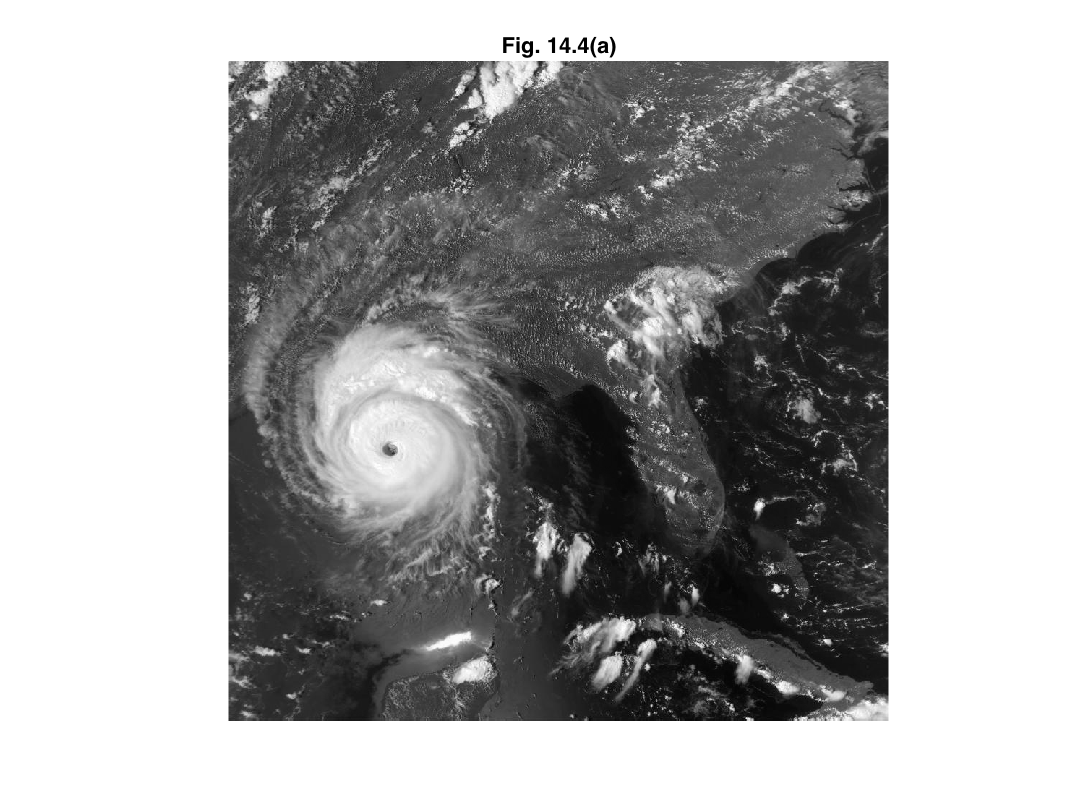

f = imread('hurricane-andrew.tif');
w = imread('hurricane-andrew-eye.tif');
figure, imshow(f), title('Fig. 14.4(a)')

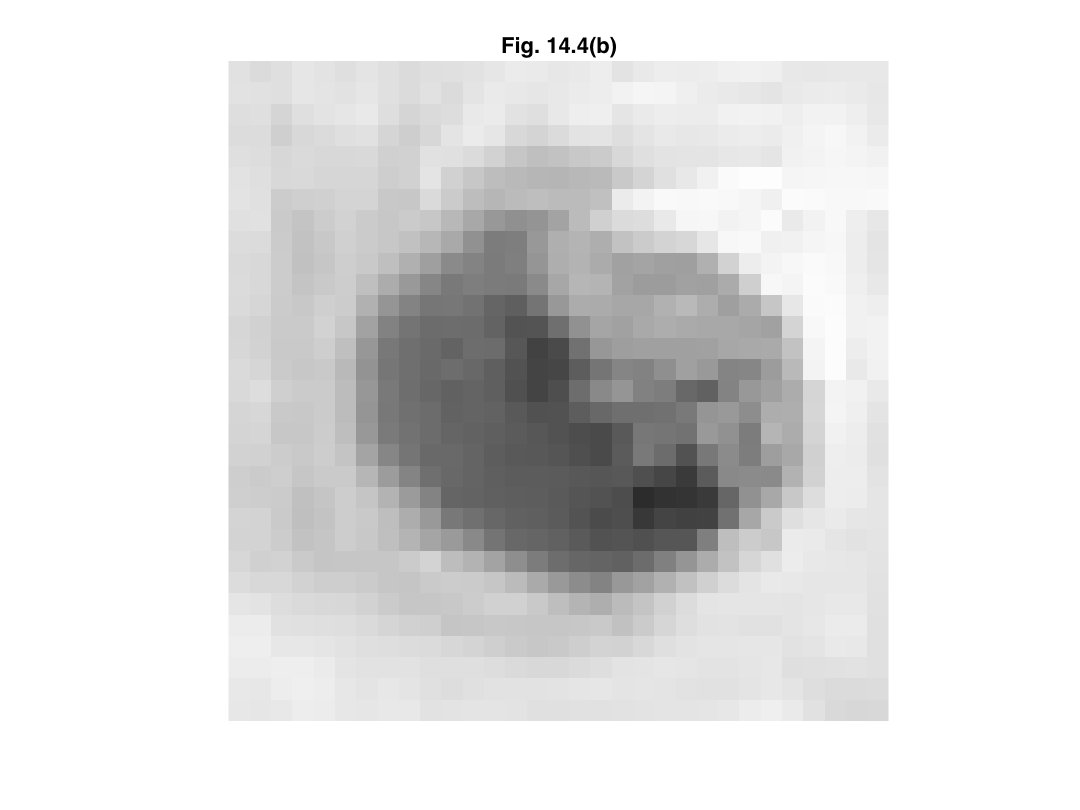

figure, imshow(w), title('Fig. 14.4(b)')

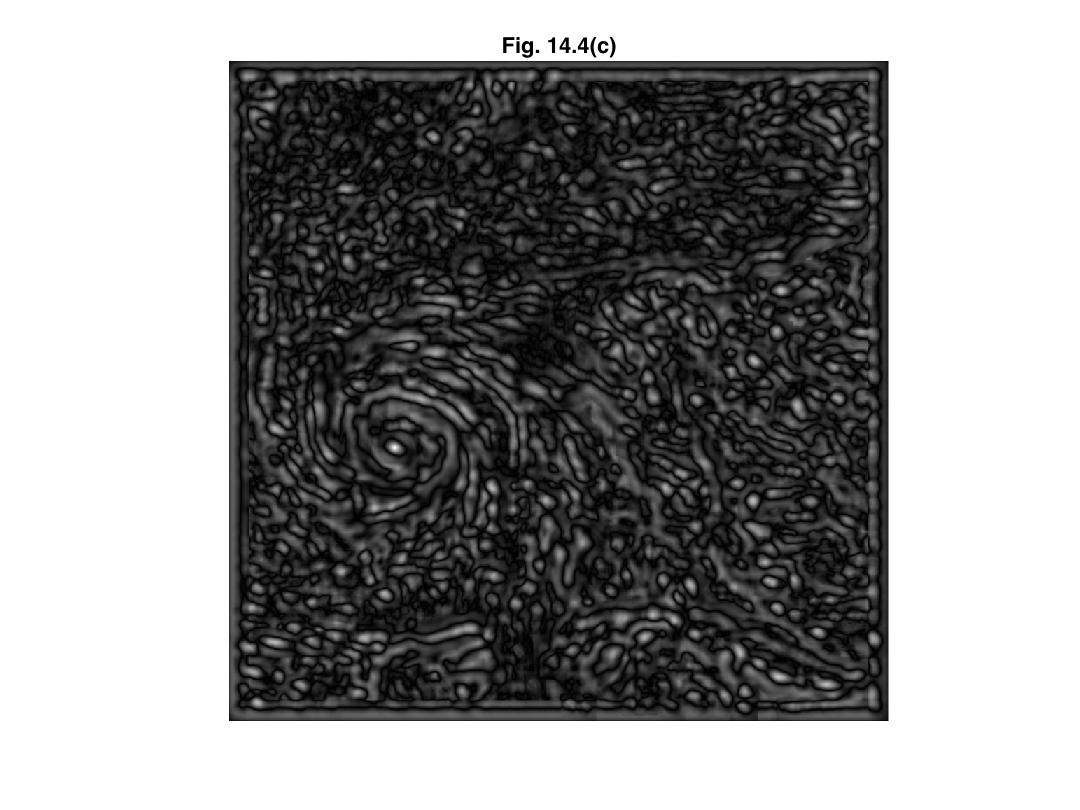

% Compute the correlation coefficient.
g = abs(normxcorr2(w,f));
figure, imshow(g,[]), title('Fig. 14.4(c)')

% Find all the max values.
gT = g == max(g(:)); % gT is a logical array.

% Find out how many peaks there are.
idx = find(gT == 1); % We use idx again later in this example.
disp(numel(idx))

     1



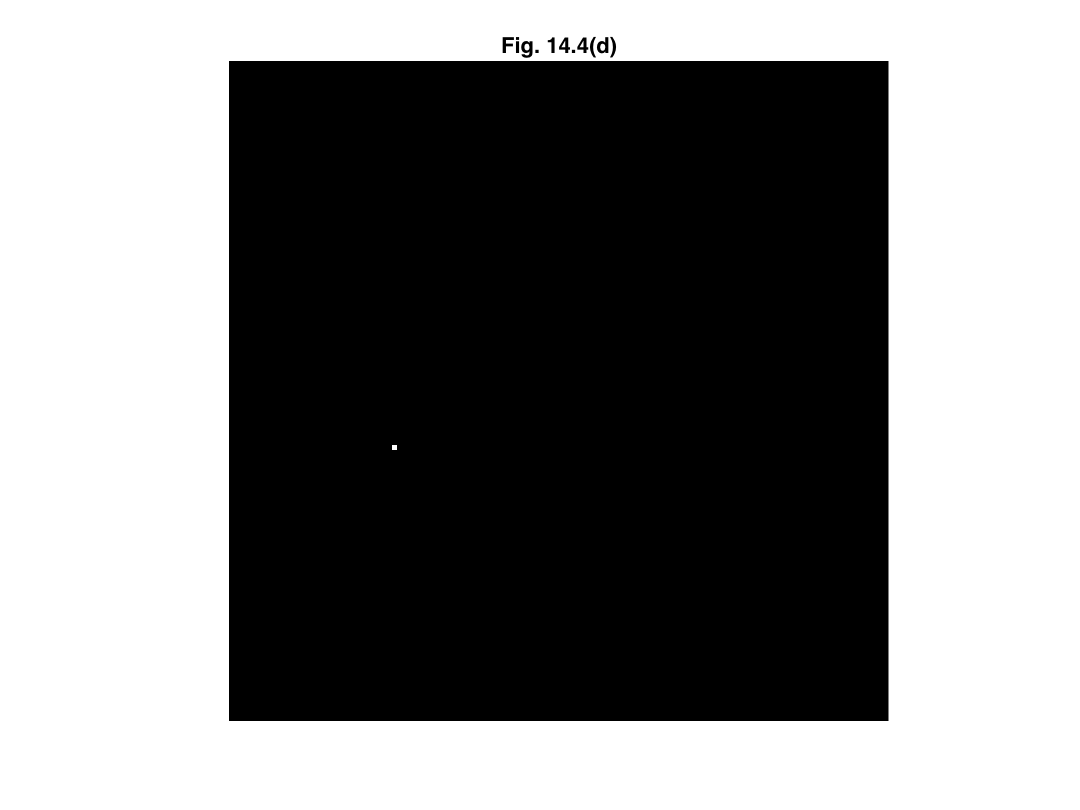

% A single point is hard to see. Increase its size using dilation.
gT = imdilate(gT,ones(7));
figure, imshow(gT), title('Fig. 14.4(d)')

The blurring in the correlation image in Fig. 14.4(c) should not be a surprise because the template in Fig. 14.4 (b) has two dominant, nearly constant regions and thus behaves like a lowpass filter kernel. 

The brightest area in Fig. 14.4(c) corresponds to the best match between the template and the original image. As you can see, the best match corresponds quite closely with the location of the eye of the storm in Fig. 14.4(a). 

Ultimately, interest is in the location of the best match (or matches) which, for correlation, implies finding the location(s) of the highest value in the correlation image: 				

[r,c] = ind2sub(size(gT),idx);
disp([r,c])

   553   238



which agrees with the location of the single white dot in Fig. 14.4(d). We used the size of `gT` instead of the size of `f` to determine location because the correlation image is larger than `f` due to padding. 